6.1. Szimulációk MATLAB-ban

6.1.1 LMS algoritmus

clear all
M = 2000;
mu = 0.0001;

n = 300000;
fs = 10e3;
Ts = 1/fs;
t = [0:n-1]'*Ts;
x = randn(n,1); % Gaussian white noise

% Chebyshev1 IIR filter
[B,A] = cheby1(5,2,200/(fs/2));
y = filter(B,A,x);

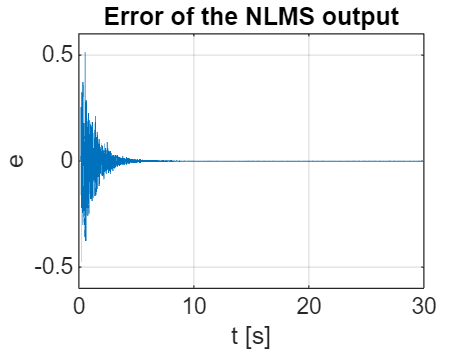

[e,w] = lms_adaptive(mu,M,x,y);

plot(t,e)
title('Error of the NLMS output')
xlabel('t [s]')
ylabel('e')
grid on

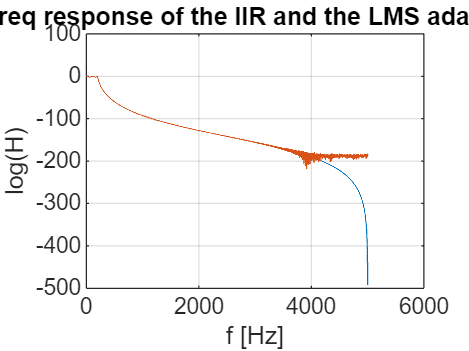


[H_IIR, f_IIR] = freqz(B,A,10e3,fs);
[Hw, fw] = freqz(w,1,10e3,fs);
plot(f_IIR,20*log10(abs(H_IIR)),fw,20*log10(abs(Hw)))
title('Freq response of the IIR and the LMS adaptive')
xlabel('f [Hz]')
ylabel('log(H)')
grid on

6.1.2 NLMS algoritmus

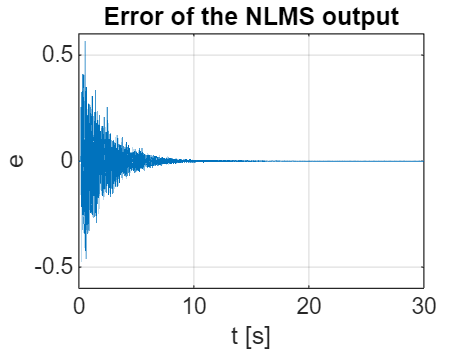

M = 2000;
mu = 0.1;
a = 0.1;
[e,w] = nlms_adaptive(mu,M,x,y,a);

plot(t,e)
title('Error of the NLMS output')
xlabel('t [s]')
ylabel('e')
grid on

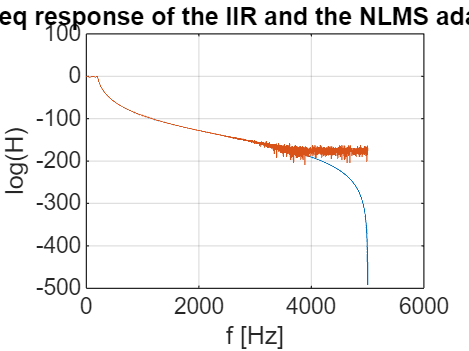


[H_IIR, f_IIR] = freqz(B,A,10e3,fs);
[Hw, fw] = freqz(w,1,10e3,fs);
plot(f_IIR,20*log10(abs(H_IIR)),fw,20*log10(abs(Hw)))
title('Freq response of the IIR and the NLMS adaptive')
xlabel('f [Hz]')
ylabel('log(H)')
grid on

6.1.3 FxLMS algoritmus

% creating S(z)
fc = 1000;
fstop = 2000;
h_s = firls(100,[0 fc fstop fs/2]/(fs/2),[1,1,0,0],[1 0.8]);

% adaptive filter C(z) for S(z)
M = 2000;
mu = 0.00001;
y_s = filter(h_s,1,x);
[e,h_c] = lms_adaptive(mu,M,x,y);

% Chebyshev1 IIR filter
[B,A] = cheby1(5,2,200/(fs/2));
y = filter(B,A,x);
[e,w] = fxlms_adaptive(mu,M,h_s,h_c,x,y)

e =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0005
    0.0007


w =    -0.0008
   -0.0009
   -0.0009
   -0.0009
   -0.0009
   -0.0009
   -0.0008
   -0.0008
   -0.0008
   -0.0008


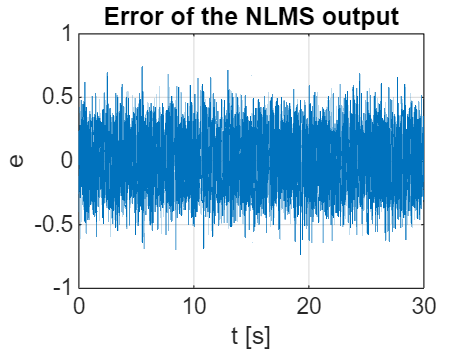


plot(t,e)
title('Error of the NLMS output')
xlabel('t [s]')
ylabel('e')
grid on

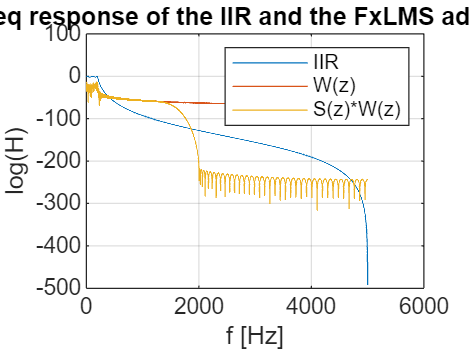


[H_IIR, f_IIR] = freqz(B,A,10e3,fs);
w_S = conv(w,h_s);
[Hw, fw] = freqz(w,1,10e3,fs);
[Hw_S, fw_S] = freqz(w_S,1,10e3,fs);
plot(f_IIR,20*log10(abs(H_IIR)),fw,20*log10(abs(Hw)),fw_S,20*log10(abs(Hw_S)))
title('Freq response of the IIR and the FxLMS adaptive')
legend('IIR','W(z)','S(z)*W(z)')
xlabel('f [Hz]')
ylabel('log(H)')
grid on